
$$\bar a_A =\bar a_B + \bar a_{A/B_n} + \bar a_{A/B_t} \\

\bar a_A = \bar \alpha_{O/A} \times \bar r_{A/O} + \bar \omega_{C/B} \times ( \bar \omega_{C/B} \times \bar  r_{B/C})\\



\bar a_B = \bar 0 + \bar \omega_{C/B} \times (\bar \omega_{C/B} \times \bar r_{B/C}) \\


\bar a_{A/B_n} = \bar \omega_{A/B} \times (\bar \omega_{A/B} \times \bar r_{A/B}) \\

\bar a_{A/B_t} = \bar \alpha_{A/B} \times \bar r_{A/B} 
$$


Sample problem 5/14,

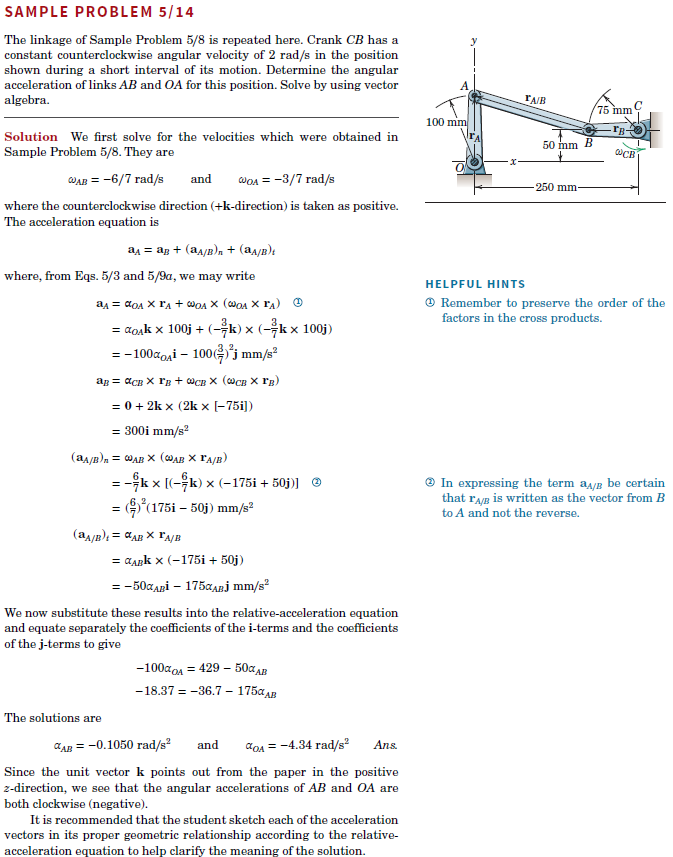

5/102 (vektorielt),

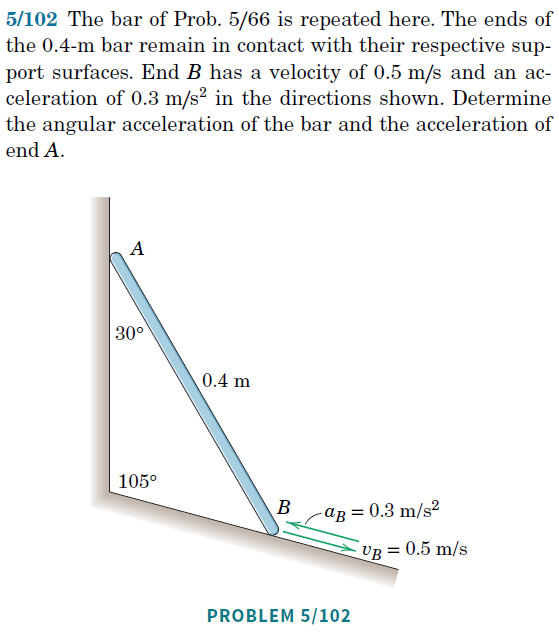

format short
u = symunit;
syms a_Aj

% Sinusrelationen
% sin(A)/a = sin(C)/c 
c = 0.4*u.m ;

% BC = sqrt(a^2+c^2 - 2 * a * c * cos d(B))
% AC = sqrt(b^2 + c^2 − 2 * b * c * cosd (A))

BC = sind(30) * c;
vpa(BC,3)

$$ans = 0.2\,m$$

AC = sqrt(BC^2 + c^2 - 2 * BC * c * cosd(180 -105 -30)) %sind(180 - 105 - 30) / sind(105) * c;

$$AC = \sqrt{\frac{1}{5}\,m^{2}-\frac{2\,\sqrt{2}}{25}\,m^{2}}$$

vpa(AC,3)

$$ans = \sqrt{0.0869\,m^{2}}$$


vpa(sqrt(BC^2 + AC^2),3)

$$ans = \sqrt{0.127\,m^{2}}$$


accelaration_B = 0.3 * u.m/u.s^2;
hastighed_B = 0.5 * u.m/u.s;

a_A = [0
    a_Aj
    0];

a_B = [-accelaration_B*cosd(105 - 90)
    accelaration_B * sind(105 - 90)
    0];

hastighed_tang = sind(180-105-30) * hastighed_B;
omega_AB_k = hastighed_tang / c;

omega_AB = [0        %-hastighed_B*cosd(105 - 90)
    0            %  hastighed_B * sind(105 - 90)
    omega_AB_k];


r_AB_x = BC *cosd(105 - 90)

$$r\_AB\_x = \frac{8700286382685973}{45035996273704960}\,m$$

r_AB_y = BC *sind(105 - 90) + AC 

$$r\_AB\_y = \frac{58280867754005}{1125899906842624}\,m+\sqrt{\frac{1}{5}\,m^{2}-\frac{2\,\sqrt{2}}{25}\,m^{2}}$$


r_AB = [-r_AB_x 
    r_AB_y
    0];


aceleration_tang = sind(45) * accelaration_B; % sind(180-105-30)
alpha_k = aceleration_tang / c/2;

alpha_AB = [0
    0
    alpha_k];
vpa(alpha_AB,4)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0.2652\,\frac{1}{s^{2}} \end{array}\right)$$


a_AB_n = cross(omega_AB, cross(omega_AB, r_AB)) 

$$a\_AB\_n = \left(\begin{array}{c} \frac{43501431913429865}{288230376151711744}\,\frac{m}{s^{2}}\\ -\frac{25\,\left(\frac{58280867754005}{1125899906842624}\,m+\sqrt{\frac{1}{5}\,m^{2}-\frac{2\,\sqrt{2}}{25}\,m^{2}}\right)}{32}\,\frac{1}{s^{2}}\\ 0 \end{array}\right)$$


a_AB_t = cross(alpha_AB, r_AB)

$$a\_AB\_t = \left(\begin{array}{c} -\frac{3\,\sqrt{2}\,\left(\frac{58280867754005}{1125899906842624}\,m+\sqrt{\frac{1}{5}\,m^{2}-\frac{2\,\sqrt{2}}{25}\,m^{2}}\right)}{16}\,\frac{1}{s^{2}}\\ -\frac{26100859148057919\,\sqrt{2}}{720575940379279360}\,\frac{m}{s^{2}}\\ 0 \end{array}\right)$$


eq = a_A == a_B + a_AB_n + a_AB_t

$$eq = \begin{array}{l} \left(\begin{array}{c} 0=-\frac{200106586801777379}{1441151880758558720}\,\sigma_{2}-\frac{3\,\sqrt{2}\,\sigma_{1}}{16}\,\frac{1}{s^{2}}\\ a_{\mathrm{Aj}}=\frac{174842603262015}{2251799813685248}\,\sigma_{2}-\frac{25\,\sigma_{1}}{32}\,\frac{1}{s^{2}}-\frac{26100859148057919\,\sqrt{2}}{720575940379279360}\,\sigma_{2}\\ 0=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{58280867754005}{1125899906842624}\,m+\sqrt{\frac{1}{5}\,m^{2}-\frac{2\,\sqrt{2}}{25}\,m^{2}}\\ \sigma_{2}=\frac{m}{s^{2}} \end{array}$$

vpa(eq)

$$ans = \begin{array}{l} \left(\begin{array}{c} 0.0=-0.26516504294495532165031663578932\,\sigma_{1}\,\frac{1}{s^{2}}-0.13885183752905356988072149704294\,\frac{m}{s^{2}}\\ a_{\mathrm{Aj}}=0.026419760888839771238850508323541\,\frac{m}{s^{2}}-0.78125\,\sigma_{1}\,\frac{1}{s^{2}}\\ 0.0=0.0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.051763809020504147895280766533688\,m+\sqrt{0.086862915010152396095864902063224\,m^{2}} \end{array}$$


[omega_OA_K_sol, omega_AB_K_sol] = solve( ...
    [eq(1),eq(2)], ...
    [omega_OA_K, omega_AB_K])

Unrecognized function or variable 'omega_OA_K'.

5/98 (grafisk og vektorielt),

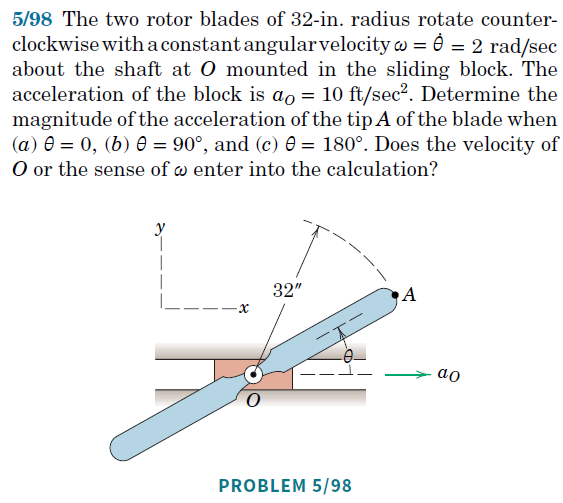

5/100, 

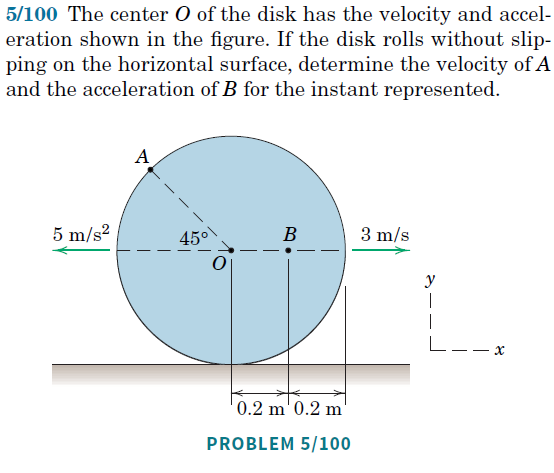

5/104,

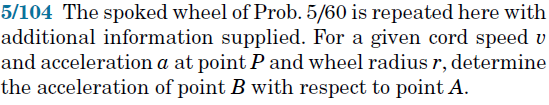

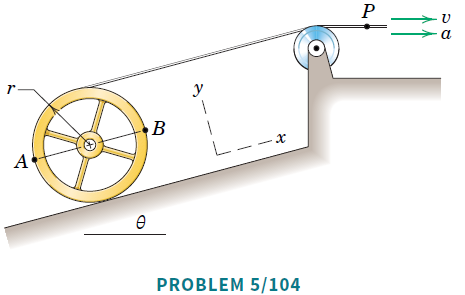

5/117 (brug information fundet i 5/88)